% Variables
wedge_angle = [5, 5, 5, 5];
x = [1, 1, 1, 1];
AoA_sweep = [0];
M_sweep = [5, 7, 10];
le_radius = 0.003; %m
T_wall_guess = 1000.0; % Wall Temp Guess K

Tw = [];
Qw = [];
Qerr = [];

% General Constants
gamma = 1.362;
T_sweep = [221.08, 225.5, 233.1]; %K
P_sweep = [2744, 1397, 686]; %Pa
V_sweep = [1490, 2107, 3061]; %m/s
T0_sweep = [1326.46, 2435, 4895];
R = 287; %J/kgK
Pr = 0.715; % Prandtl No.
sigma = 5.67e-8; % Stefan-Boltzman constant
epsilon = 0.95; % material emissivity
CPw = 1700; % j/kgK specific heat

MU_ref = 1.827e-5; % kg/m-s
Tref = 291.15; % K
C = 120; %K
CP_air = 1006; % j/kgK

% T_plot = zeros(3, 60);
% Q_plot = zeros(3, 60);

    jj = 1:length(M_sweep);
    M_inf = M_sweep(jj);
    T_inf = T_sweep(jj);
    P_inf = P_sweep(jj);
    V_inf = V_sweep(jj);


for iii = 1:length(M_sweep)

    % jj = 1;
    % M_inf = M_sweep(jj);
    % T_inf = T_sweep(jj);
    % P_inf = P_sweep(jj);
    % V_inf = V_sweep(jj);
    % q = (gamma / 2) * P_inf * M_inf^2;

    % Freestream Isentropic Solutions
    T_0 = T0_sweep(iii);
    P_0 = isen_p0(P_inf(iii), M_inf(iii), gamma);
    rho_inf = P_inf(iii) / (R * T_inf(iii));

    % MU_st = MU_ref*((Tref+C)/(T_0+C))*((T_0/Tref)**(1.5))  % viscosity based on sutherlands law
    MU_st = sutherlands(T_0, MU_ref, Tref, C);

    % Normal Shock Solutions
    gp1 = gamma + 1;
    gm1 = gamma - 1;
    gogm1 = gamma / gm1;
    s = [0];
    P_st1 = (gp1 * M_inf(iii)^2 / (2 + gm1 * M_inf(iii)^2))^gogm1;
    P_st2 = (gp1 / (2 * gamma * M_inf(iii)^2 - gm1))^(1 / gm1);
    P_st = P_0 * P_st1 * P_st2;

    % rho_0 = isen_rho0(rho_inf, M_inf, gamma)
    rho_0 = rho_inf * (gp1 * M_inf(iii)^2) / (gm1 * M_inf(iii)^2 + 2);

    % Heat Balance
    enthalpy_wall_ad = CP_air * T_0 + 0.5 * V_inf(iii)^2; % adiabatic wall enthalpy
    Dustods = (1 / le_radius) * ((2 * (P_0 - P_inf(iii))) / rho_0)^0.5;

    % T_iso = shock_solutions.find_Tiso(T_wall_guess, CPw, sigma, epsilon, Pr, rho_0, MU_st, enthalpy_wall_ad, Dustods)

    T_wall = 1000; % Initial guess for T_wall
    i = 0;

    while i <= 19
        T_iso = T_wall(end);
        Hw = CPw * T_iso;
        Qr = sigma * epsilon * (T_iso^4);

        % Qr = 0; % Uncomment this line if radiation heat transfer is intended to be zero

        Qstgw = 0.57 * (Pr^(-0.6)) * ((rho_0 * MU_st)^0.5) * (enthalpy_wall_ad - Hw) * (Dustods^0.5);

        Qerr = [Qerr, Qstgw - Qr];
        if i > 1
            if abs(Qerr(end)) <= 1e-6
                T_iso = T_wall(end);
                break;
            end
        end

        if i <= 1
            T_wall = [T_wall, T_wall(end) + 1.0];
        end

        if i > 1
            T_wall = [T_wall, T_wall(end) - Qerr(end) / ((Qerr(end) - Qerr(end - 1)) / (T_wall(end) - T_wall(end - 1)))];
        end

        i = i + 1;
    end

    wall_enthalpy = CPw * T_iso;
    Qstgw = 0.57 * (Pr^(-0.6)) * ((rho_0 * MU_st)^0.5) * (enthalpy_wall_ad - wall_enthalpy) * (Dustods^0.5);

    Tw = [Tw, T_iso];
    Qw = [Qw, Qstgw];


    % Leading Edge Tip Curvature
    Qw_tip = Qstgw;
    num_pts = 21;
    theta_tip = linspace(0, pi/2 - deg2rad(wedge_angle(3)), num_pts);
    theta_tip = theta_tip(2:end-1);
    d_theta = pi/2 / num_pts;

    for theta = theta_tip
        s = [s, theta * le_radius];
        G = (1 - 1 / (gamma * M_inf(iii)^2)) * (theta^2 - 0.5 * theta * sin(4 * theta) + 0.125 * (1 - cos(4 * theta))) ...
            + (4 / (gamma * M_inf(iii)^2)) * (theta^2 - theta * sin(2 * theta) + 0.5 * (1 - cos(2 * theta)));
        Qw_tip = Qstgw * 2 * theta * sin(theta) * (1 - 1 / (gamma * M_inf(iii)^2)) * G^(-0.5);
        theta_end = rad2deg(theta);
        Tw = [Tw, T_iso];
        Qw = [Qw, Qw_tip];
    end

    for AoA = AoA_sweep

        for alpha = wedge_angle
            if i == 1
                % Stage 1
                if AoA <= alpha
                    theta = alpha - AoA;
                    [P_2, T_2, M2, beta] = oblique(abs(theta), M_inf, P_inf, T_inf);
                    M = [M, M2];
                    T = [T, T_2];
                    P = [P, P_2];
                elseif AoA > alpha
                    theta = AoA - alpha;
                    [P_2, T_2, M2] = PM_sol(abs(theta), M(end), P(end), T(end));
                    M = [M, M2];
                    T = [T, T_2];
                    P = [P, P_2];
                end
                L = [L, P(i) * cos(deg2rad(AoA - alpha)) * (x(i) / cos(deg2rad(alpha)))];
                D = [D, P(i) * sin(deg2rad(AoA - alpha)) * (x(i) / cos(deg2rad(alpha)))];
            elseif i == 2
                % Stage 2
                theta = wedge_angle(i-1) + alpha;
                [P_2, T_2, M2] = PM_sol(abs(theta), M(end), P(end), T(end));
                M = [M, M2];
                T = [T, T_2];
                P = [P, P_2];
                L = [L, P(i) * cos(deg2rad(AoA + alpha)) * (x(i) / cos(deg2rad(alpha)))];
                D = [D, P(i) * sin(deg2rad(AoA + alpha)) * (x(i) / cos(deg2rad(alpha)))];
            elseif i == 3
                % Stage 3
                if AoA < 0 && abs(AoA) > alpha
                    theta = alpha + AoA;
                    [P_2, T_2, M2] = PM_sol(abs(theta), M_inf, P_inf, T_inf);
                    M = [M, M2];
                    T = [T, T_2];
                    P = [P, P_2];
                elseif AoA >= 0
                    theta = AoA + alpha;
                    [P_2, T_2, M2, beta] = oblique(abs(theta), M_inf, P_inf, T_inf);
                    M = [M, M2];
                    T = [T, T_2];
                    P = [P, P_2];
                end

                Te = T_2;
                Me = M2;
                Pe = P_2;
                Ue = Me * sqrt(gamma * R * Te);
                rho_e = Pe / (R * Te);
                recover = Pr^0.5;
                He_adiabatic_wall = CP_air * Te + recover * 0.5 * (Ue^2);
                size = 40;
                y = cos(deg2rad(alpha)) * le_radius * sin(rad2deg(alpha));
                smax = x(i) / cos(deg2rad(alpha));
                sinc = (smax - s(end)) / (size - 1);
                slast = s(end);
                T_wall = [T_iso];

                for ii = 1:40
                    s = [s, slast + (ii - 1) * sinc];
                    mu_e = sutherlands(Te, MU_ref, Tref, C); % viscosity based on sutherlands law
                    Rey = ((rho_e * Ue * (s(end)) + y - slast) / mu_e);

                    % T_iso solution
                    Qerr = [];
                    for j = 1:20
                        T_iso = T_wall(end);
                        Qr = sigma * epsilon * T_iso^4;
                        Ts = Te * (0.5 + 0.039 * Me^2 + 0.5 * (T_iso / Te));
                        CFs = 0.664 * (Ts / Te)^(-1/6) * Rey^(-0.5);
                        Prs = ((T_iso / Te) - 1) * (2 / (gm1 * Me^2))^2;
                        CH = CFs / (2 * Prs^(2/3));
                        Hw = CPw * T_iso;
                        Qfgw = CH * rho_e * Ue * (He_adiabatic_wall - Hw);
                        Qerr = [Qerr, Qfgw - Qr];

                        if j > 1
                            if abs(Qerr(end)) < 1e-6 || Qerr(end - 1) - Qerr(end) == 0.0
                                T_iso = T_wall(end);
                                break;
                            end
                        end

                        if j <= 1
                            T_wall = [T_wall, T_wall(end) + 1.0];
                        end

                        if j > 1
                            T_wall = [T_wall, T_wall(end) - Qerr(end) / ((Qerr(end) - Qerr(end - 1)) / (T_wall(end) - T_wall(end - 1)))];
                        end

                    end
                    Tw = [Tw, T_iso];
                    Qw = [Qw, Qfgw];
                end

                L = [L, P(i) * cos(deg2rad(AoA + alpha)) * (x(i) / cos(deg2rad(alpha)))];
                D = [D, P(i) * sin(deg2rad(AoA + alpha)) * (x(i) / cos(deg2rad(alpha)))];
            elseif i == 4
                % Stage 4
                theta = wedge_angle(i - 1) + alpha;
                [P_2, T_2, M2] = PM_sol(abs(theta), M(end), P(end), T(end));
                M = [M, M2];
                T = [T, T_2];
                P = [P, P_2];
                L = [L, P(i) * cos(deg2rad(AoA - alpha)) * (x(i) / cos(deg2rad(alpha)))];
                D = [D, P(i) * sin(deg2rad(AoA - alpha)) * (x(i) / cos(deg2rad(alpha)))];
            end
            i = i + 1;
        end  
    end
end

    tw_5 = Tw(1:20);        
    tw_7 = Tw(21:40);
    tw_10 = Tw(41:60);
    qw_5 = Qw(1:20);        
    qw_7 = Qw(21:40);
    qw_10 = Qw(41:60);

% Plotting CL/CD Plots
% Cl = Lift / q(jj);
% Cd = Drag / q(jj);
% Cl_Cd(jj, :) = Cl ./ Cd;

%jj = jj + 1;


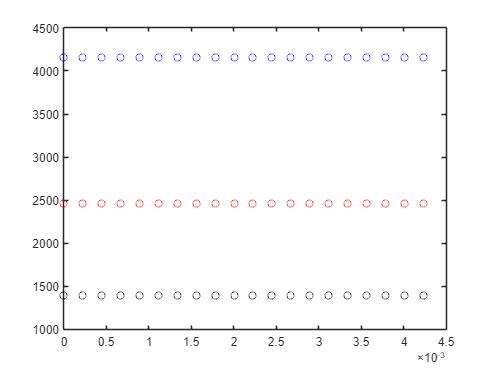

% Plotting T_iso

figure
plot(s,tw_5,'ko')
hold on
plot(s,tw_7,'ro')
plot(s,tw_10,'bo')
hold off

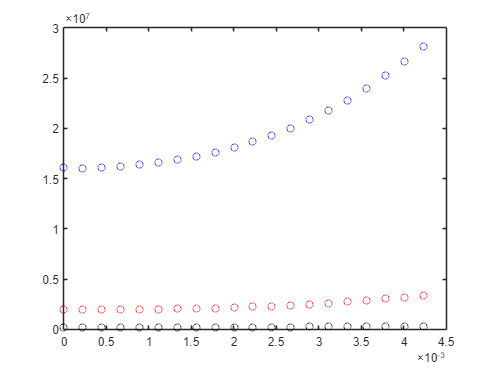


% Plotting Q_iso

figure
plot(s,qw_5,'ko')
hold on
plot(s,qw_7,'ro')
plot(s,qw_10,'bo')
hold off